%% 資料前處理
data = load('ts26.dat');
data = reshape(data', [], 1);
data = data * (1/30);  % 縮放到 [0, 1]

% 構建 H(i) = [y(t-2), y(t-1), y(t)], d(i) = y(t+1)
num_samples = 597;
X = zeros(num_samples, 3);
Y = zeros(num_samples, 1);
for i = 1:num_samples
    t = i + 2;
    X(i, :) = [data(t-2), data(t-1), data(t)];
    Y(i) = data(t + 1);
end
H_train = X(1:300, :);
Y_train = Y(1:300);
H_test = X(301:end, :);
Y_test = Y(301:end);

addpath("PSO+RLSE CFIS for StarBrightness\Model\",".\PSO+RLSE CFIS for StarBrightness\Model\Result\");

%使用optimizer找出模型最佳參數
tIter = 20;
[ifParm, cnsqParm, baseVarFuzzyN, lossAll] = optimizer(H_train, Y_train, tIter);

    0.0193
    0.0224
    0.0272
    0.0185
    0.0177
    0.0178
    0.0171
    0.0203
    0.0189
    0.0169
    0.0177
    0.0174
    0.0172
    0.0181
    0.0188
    0.0170
    0.0174
    0.0179
    0.0173
    0.0181
    0.0180
    0.0172
    0.0184
    0.0175
    0.0181
    0.0212
    0.0181
    0.0185
    0.0178
    0.0186
    0.0172
    0.0189
    0.0174
    0.0174
    0.0177
    0.0171
    0.0171
    0.0192
    0.0190
    0.0206
    0.0255
    0.0171
    0.0171
    0.0182
    0.0175
    0.0207
    0.0172
    0.0172
    0.0173
    0.0171
    0.0175
    0.0173
    0.0193
    0.0212
    0.0187
    0.0176
    0.0170
    0.0171
    0.0184
    0.0172

1 0.016887
    0.0173
    0.0208
    0.0179
    0.0185
    0.0177
    0.0178
    0.0171
    0.0171
    0.0170
    0.0169
    0.0168
    0.0174
    0.0172
    0.0181
    0.0172
    0.0170
    0.0174
    0.0171
    0.0173
    0.0181
    0.0170
    0.0172
    0.0179
    0.0175
    0.0173
    0.0180
    0.0179
    0.0171
    0.0171
    0.017


%使用approxiamtor預測資料
Y_predict_train = approximator(H_train, ifParm, cnsqParm, baseVarFuzzyN);
Y_predict_test = approximator(H_test, ifParm, cnsqParm, baseVarFuzzyN);

%輸出圖形與損失值
printLoss(Y_predict_train, Y_train, Y_predict_test, Y_test);

train data sse=0.081989, test data sse=0.103578
train data mse=0.000273, test data mse=0.000349
train data rmse=0.016532, test data rmse=0.018675
train data nmse=0.003090, test data nmse=0.003905


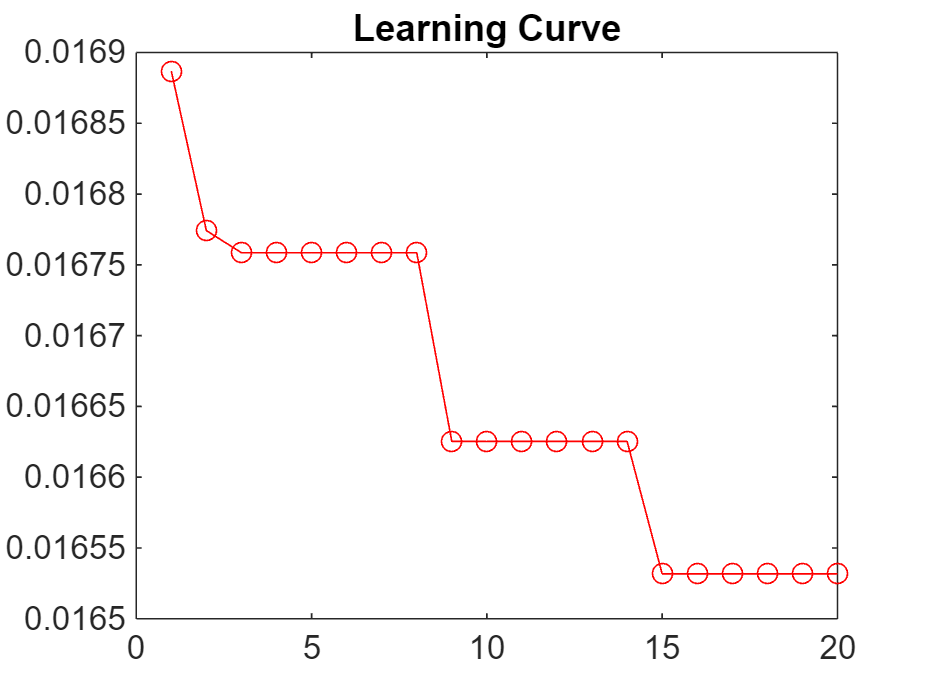

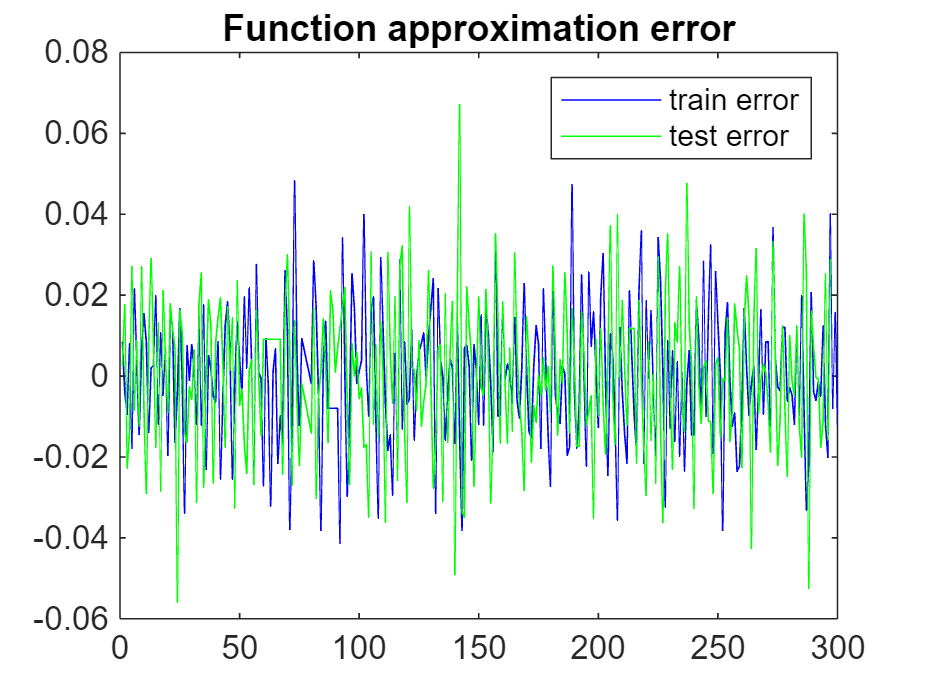

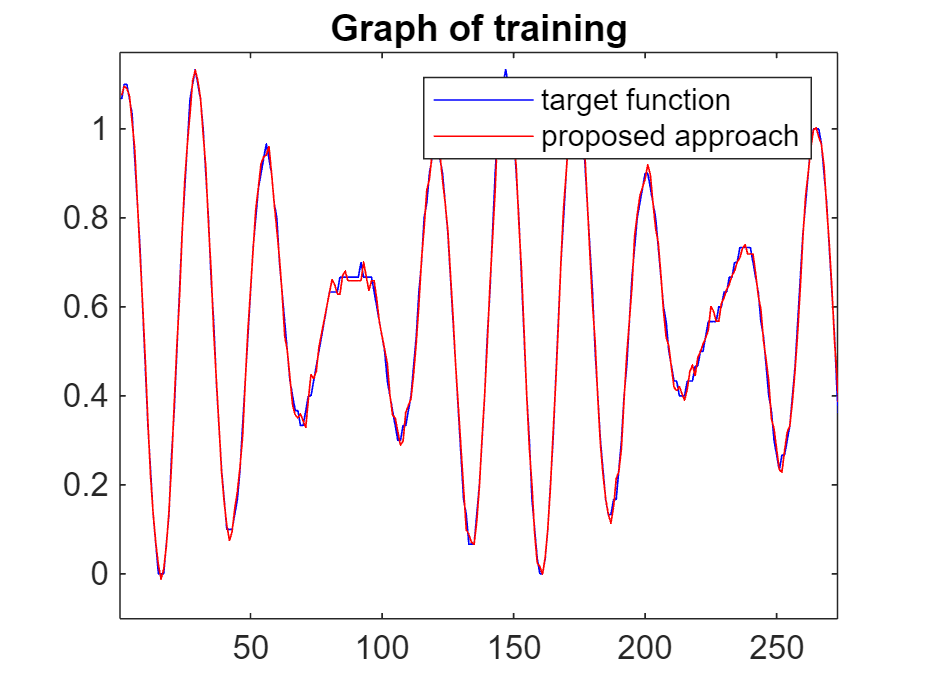

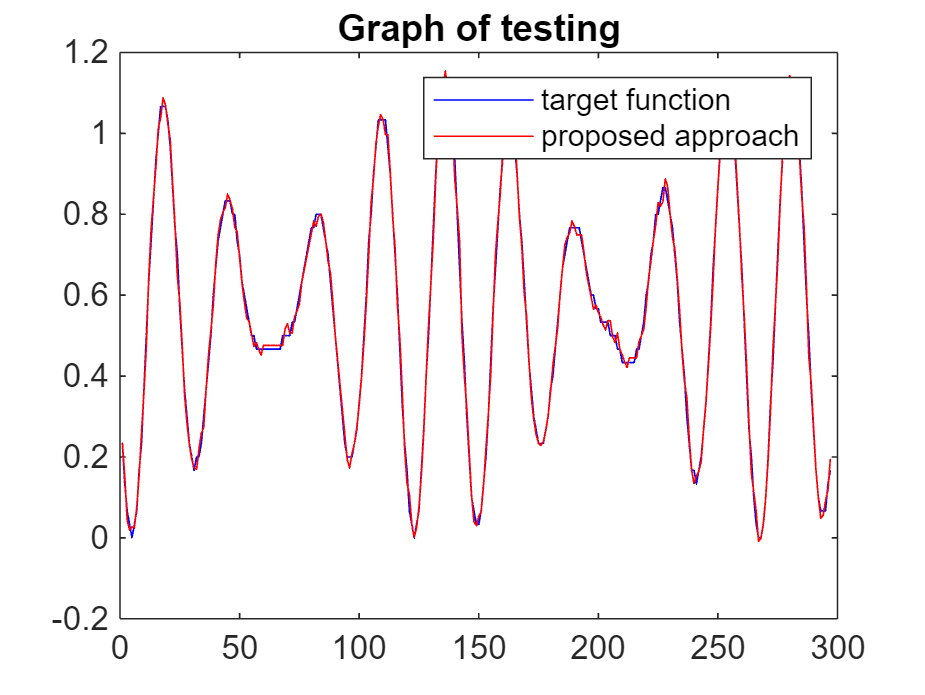

model_plot([Y_predict_train,Y_train],[Y_predict_test,Y_test], lossAll );


rmpath(".\Model\",".\Dataset\",".\Model\Result\");